clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## Same real uncertainty for every input with alpha = 0


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,0,{[-1,1]},0);

Evaluation of design procedure for three-step SOF 
Eigenvalues of the decoupled systems are all negative 


ans =   -3.7230 + 0.0000i  -0.1570 + 0.5455i  -0.1570 - 0.5455i  -3.7410 + 0.0000i  -0.1672 + 0.5510i  -0.1672 - 0.5510i  -3.6909 + 0.0000i  -0.1730 + 0.5548i  -0.1730 - 0.5548i  -3.6894 + 0.0000i  -0.1738 + 0.5593i  -0.1738 - 0.5593i


Eigenvalues of the coupled systems are all negative 


ans =   -3.4587 + 0.0000i  -3.3013 + 0.0000i  -3.2463 + 0.0000i  -3.1610 + 0.0000i  -0.2945 + 0.7349i  -0.2945 - 0.7349i  -0.3686 + 0.8275i  -0.3686 - 0.8275i  -0.4083 + 0.8539i  -0.4083 - 0.8539i  -0.4380 + 0.8739i  -0.4380 - 0.8739i


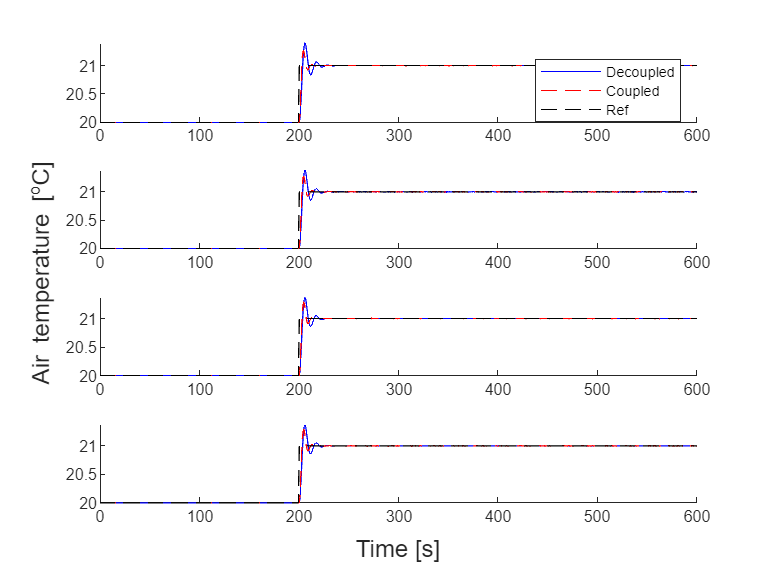

util.SimulateLinearStep(param,"Examination_Output_Feedback_alpha0",0);

## Same real uncertainty for every input with alpha = 0.5


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,0,{[-1,1]},.25);

Evaluation of design procedure for three-step SOF 
Eigenvalues of the decoupled systems are all negative 


ans =   -3.3528 + 0.0000i  -0.3421 + 0.7793i  -0.3421 - 0.7793i  -3.3527 + 0.0000i  -0.3613 + 0.7830i  -0.3613 - 0.7830i  -3.2858 + 0.0000i  -0.3756 + 0.7877i  -0.3756 - 0.7877i  -3.2943 + 0.0000i  -0.3713 + 0.7901i  -0.3713 - 0.7901i


Eigenvalues of the coupled systems are all negative 


ans =   -0.7193 + 1.0721i  -0.7193 - 1.0721i  -0.9795 + 1.2905i  -0.9795 - 1.2905i  -1.1911 + 1.4927i  -1.1911 - 1.4927i  -1.1082 + 1.3896i  -1.1082 - 1.3896i  -2.6089 + 0.0000i  -2.0778 + 0.0000i  -1.8485 + 0.0000i  -1.6550 + 0.0000i


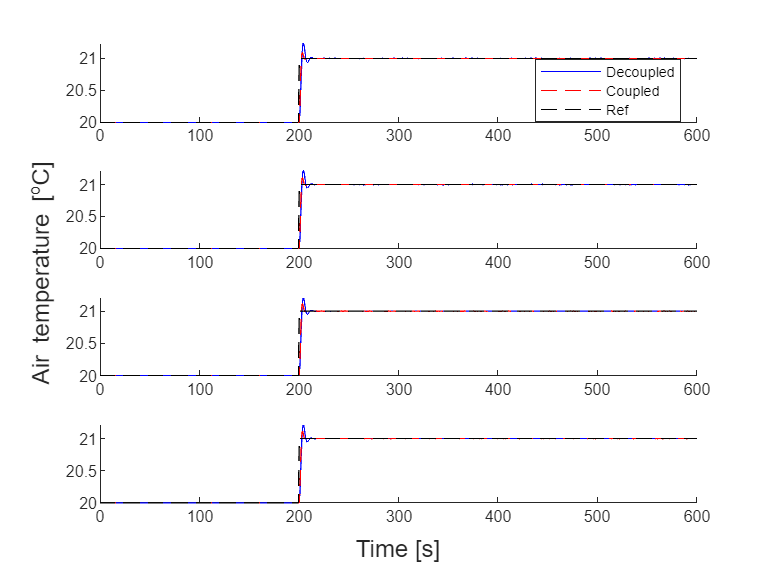

util.SimulateLinearStep(param,"Examination_Output_Feedback_alpha",0);

clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## Same real uncertainty for every input with alpha = 0


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF_ILMI(param,0,{[-1,1]},1);

Evaluation of design procedure for ILMI SOF 
Eigenvalues of the decoupled systems are all negative 


ans =    -3.4840   -0.4553   -0.0976   -3.4354   -0.5319   -0.1081   -3.4087   -0.5155   -0.1128   -3.4100   -0.5179   -0.1090


Eigenvalues of the coupled systems are all negative 


ans =   -2.7746 + 0.0000i  -1.9843 + 0.8617i  -1.9843 - 0.8617i  -1.9694 + 0.9248i  -1.9694 - 0.9248i  -1.1716 + 0.0000i  -1.9722 + 0.3801i  -1.9722 - 0.3801i  -0.0890 + 0.0000i  -0.1021 + 0.0000i  -0.0991 + 0.0000i  -0.0981 + 0.0000i


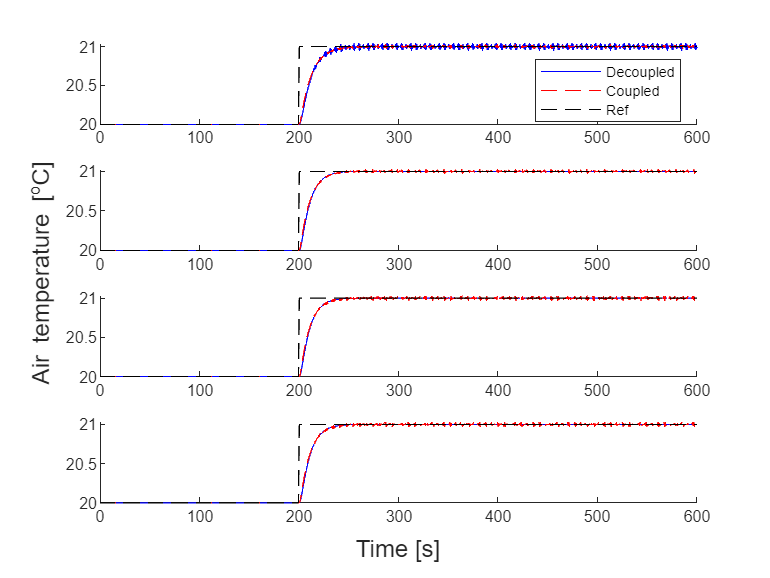

util.SimulateLinearStep(param,"Examination_Output_Feedback_ILMI",0);